%Fecha de actualización: 08/Abril/2023
%clc
%clear all

Portada

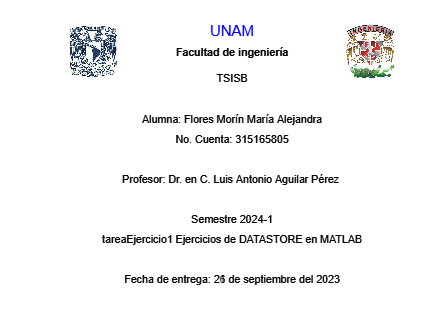

figure(15);
% tamaño de la figura
%  set(gcf, 'Position', [100, 100, 800, 600]);
tamano_letra=10;
% Cargar y mostrar la primera imagen
img1 = imread('UNAMlogo.png');  % Reemplaza 'imagen1.jpg' con el nombre de tu primera imagen
subplot(4, 4, 1);  % Divide la figura en 1 fila y 2 columnas, y selecciona la primera posición
imshow(img1);

% Cargar y mostrar la segunda imagen
img2 = imread('FIlogo.jpg');  % Reemplaza 'imagen2.jpg' con el nombre de tu segunda imagen
subplot(4, 4, 4);  % Selecciona la segunda posición
imshow(img2);

% Agregar texto a un subplot específico (por ejemplo, el subplot 8)
subplot(4, 4, [2,3]); 
text(0.5, 0.9, 'UNAM', 'FontSize', 14,'HorizontalAlignment', 'center','Color','b');
text(0.5, 0.5, 'Facultad de ingeniería', 'FontSize', tamano_letra, 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
text(0.5, 0.0, 'TSISB', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
axis off
subplot(4, 4, [5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16]); 
text(0.5, 0.9, 'Alumna: Flores Morín María Alejandra', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
text(0.5, 0.8, 'No. Cuenta: 315165805', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
text(0.5, 0.6, 'Profesor: Dr. en C. Luis Antonio Aguilar Pérez ', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
text(0.5, 0.4, 'Semestre 2024-1', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
text(0.5, 0.3, 'tareaEjercicio1 Ejercicios de DATASTORE en MATLAB', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
text(0.5, 0.1, 'Fecha de entrega: 26 de septiembre del 2023', 'FontSize', tamano_letra,'HorizontalAlignment', 'center');
axis off

# Manipulación de archivos de datos

Un modelo de datos o DataFrame es una estructura de datos tabular, la cual organiza la información en filas y columnas de manera similar a una hoja de cálculo. En particular cada columna del DataFrame representa una variable o feature (atributo), mientras que cada fila representa una observación o registro realizado. Los DataFrames son utilizados comúnmente en análisis de datos para manipular y analizar grandes conjuntos de datos de forma eficiente. Existen diversos métodos de almacenar esta informacion dependiendo del lenguaje de programacion utilizado. El formato universal y más tradicional de almacenamiento de la informacion es mediante archivos de tipo CSV. Un archivo de formato CSV es en realidad un archivo en formato de codificacion de texto plano, donde cada línea del archivo representa una fila de datos, y los valores de cada columna están separados por un carácter delimitador, siendo generalmente este una coma. Es un formato popular debido a su simplicidad y fácil manipulación por programas y hojas de cálculo. Además, muchos sistemas y aplicaciones pueden exportar datos en formato CSV, lo que lo hace fácilmente intercambiable entre diferentes plataformas y herramientas. En particular un archivo de tipo CSV se visualiza de la siguiente manera:

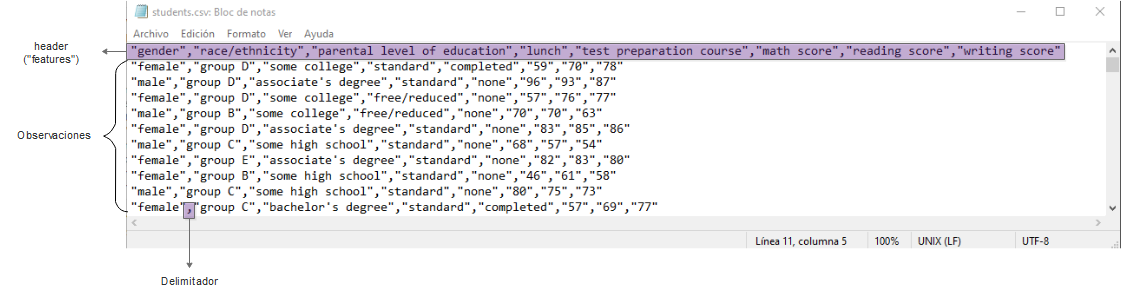

**Figura 1.-** Archivo de tipo CSV visualizado como texto plano

Existen otros formatos de archivos como el parquet, el cual es un formato de archivo de almacenamiento de datos de código abierto utilizado para almacenar datos tabulares en una estructura de columna, en lugar de una estructura de fila tradicional. Este formato está diseñado para ser eficiente en términos de almacenamiento y procesamiento, y permite una lectura y escritura más rápida de grandes conjuntos de datos. En particular, al estar los datos encriptados y codificados en este tipo de archivos, no es posible visualizarlos de manera tradicional, aunque el esquema de organizacion de la información seria lo más cercano a este:

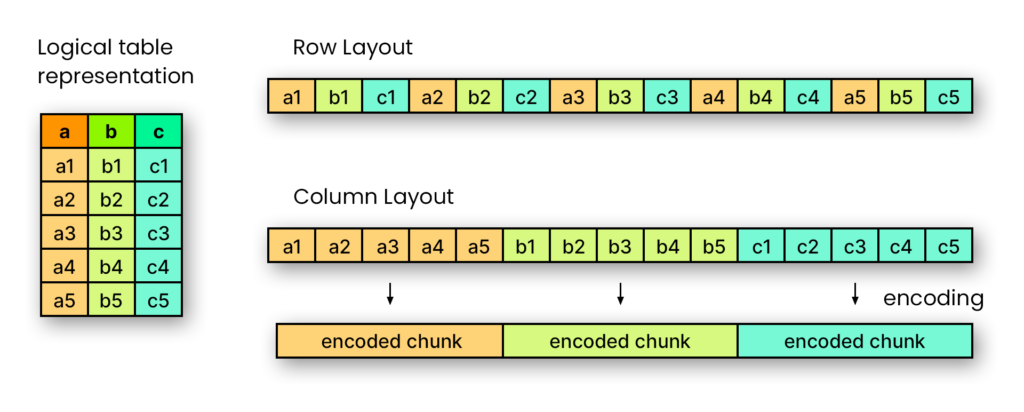

**Figura 2.-** Esquema tradicional de codificacion tipo parquet

Finalmente, el uso y manejo de modelos de datos en MATLAB se realiza mediante la funcion "Datastore". Esta es una función que proporciona una interfaz rápida para acceder a grandes conjuntos de datos, como archivos de imágenes, archivos de audio o archivos de texto, sin cargarlos en la memoria. Permite la lectura de datos de manera eficiente y escalable, ya que lee y procesa los datos de forma incremental a medida que se necesitan, lo que permite trabajar con grandes conjuntos de datos sin tener que cargarlos por completo en la memoria. Además, la función "datastore" permite realizar operaciones de preprocesamiento y manipulación de datos, como filtrado y transformación de datos, de manera eficiente y fácil. Estas bases de datos tienen la siguiente estructura de informacion 

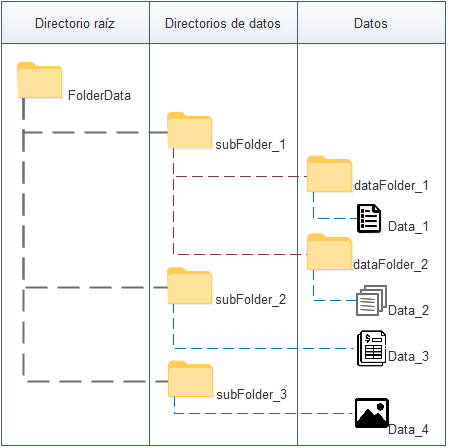

**Figura 3.-** Esquema de un modelo de datos

### --- Pasos iniciales

%%%
%Creacion de directorio de trabajo
%rootFolder = 'D:\TSISB_IA';
rootFolder ='C:\Users\puma_\Documents\TSISB_IA';
workingFolder = 'practica_2';
tempFolder = 'temp';
savePath = fullfile(rootFolder,workingFolder);
saveTempPath = fullfile(rootFolder,workingFolder,tempFolder);

prefix = ['\' 'students'];
sufix = '.csv';
newName = [prefix, sufix];

%Despues de correr esta celda una vez, crea un bloque de comentarios a partir de esta linea

if ~exist(savePath,'dir')
    [status, message, ~] = mkdir(savePath);
    if status == 0
        disp(message)
    end
end

if ~exist(saveTempPath,'dir')
    [status, message, ~] = mkdir(saveTempPath);
    if status == 0
        disp(message)
    end
end

%%%
%Organizacion y copia de archivos
[fileName, pathFileName] = uigetfile('C:\','*.txt' );

if isequal(fileName,0)
    disp('Se canceló la busqueda de archivos');
else
    disp(['El usuario seleccionó el archivo ', fullfile(pathFileName,fileName)]);
    [status, message, ~] = copyfile([pathFileName,fileName],[saveTempPath,newName]);
    if status == 0
        disp(message)
    else
        disp(['El cual se movio a la dirección ', fullfile(saveTempPath)]);
    end
end

El usuario seleccionó el archivo C:\Users\puma_\Documents\TSISB_IA\practica_2\students.csv


El cual se movio a la dirección C:\Users\puma_\Documents\TSISB_IA\practica_2\temp


%}

## °°°Modelo de datos mediante un solo archivo

Para lograr el manejo de grandes conjuntos de información, es necesario establecer un "pipeline" o flujo de trabajo de la función datastore. Este se muestra a continuación:

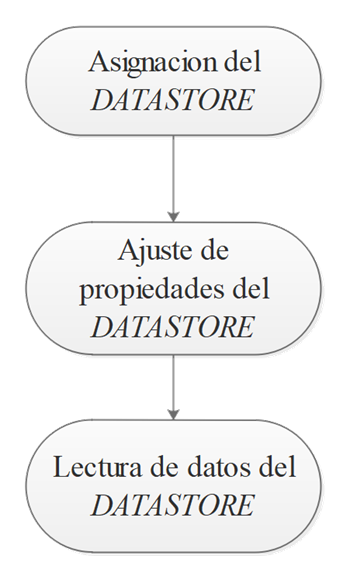

**Figura 2.-** Flujo de trabajo de un Datastore

La primer parte del pipeline del datastore incluye operaciones como:

- Detección de propiedades de los archivos del dataframe/modelo de datos

- Normalizacion de datos

%****
%En este ejercicio solo estaremos trabajando con un archivo
%contenido dentro del datastore
%****

%Se determina la direccion de los archivos que integran el "Datastore"
archivoCSV = [saveTempPath, newName];

%Visualización rápida de las primeras lineas del archivo de texto
%Como solo es un archivo se puede utilizar el comando dbtype
dbtype(archivoCSV,'1:5')

1     gender,race/ethnicity,parental level of education,lunch,test preparation course,math score,reading score,writing score
2     female,group D,some college,standard,completed,59,70,78
3     male,group D,associate's degree,standard,none,96,93,87
4     female,group D,some college,free/reduced,none,57,76,77
5     male,group B,some college,free/reduced,none,70,70,63



%Asignamos nuestro datastore dentro de MATLAB
%dsGeneral = datastore(archivoCSV)
%Si tuvieramos muchos archivos, se utilizaria el siguiente comando
%preview(dsGeneral) 

%Desde la version 2019, los nombres de las variables pueden incluir
%cualquier tipo de simbolos, ademas de no necesariamente comenzar solo
%con letras, por lo que matlab requiere el Flag "preserve" para considerar
%esta opción
%dsGeneral.VariableNamingRule='preserve';

%Selección del delimitador de texto
%dsGeneral.Delimiter=",";

%Modificacion de los nombres utilizados para cada caracteristica/feature
%values=dsGeneral.VariableNames;
%Modificacion como si fuera un indexado de valores clásico
%newValues=["hola", "esta", "es", "una", "prueba", "de", "cambio", "de variables"];
%dsGeneral.VariableNames = newValues;
%preview(dsGeneral)

## °°°Detección y modificación de propiedades de los datos contenidos en el archivo

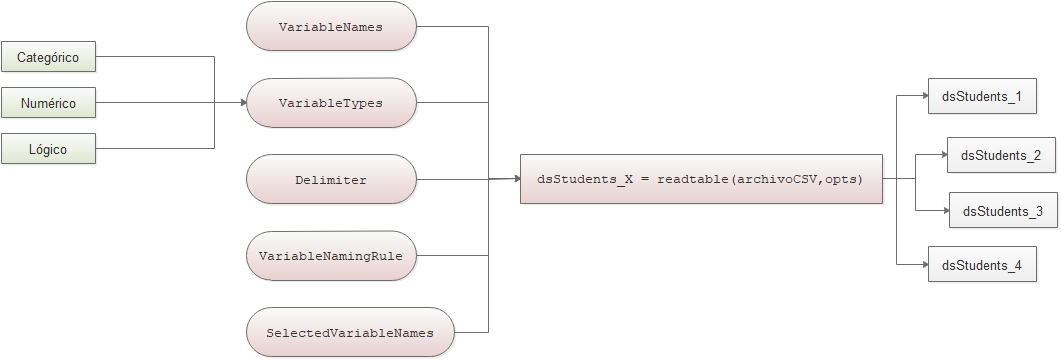

**Figura 3.- **Propiedades de un **datastore de tipo categorico-numérico**

%Visualizacion general de las opciones de importacion de los archivos
%dentro del datastore
opts = detectImportOptions(archivoCSV)

opts =   DelimitedTextImportOptions with properties:

   Format Properties:
                    Delimiter: {','}
                   Whitespace: '\b\t '
                   LineEnding: {'\n'  '\r'  '\r\n'}
                 CommentStyle: {}
    ConsecutiveDelimitersRule: 'split'
        LeadingDelimitersRule: 'keep'
       TrailingDelimitersRule: 'ignore'
                EmptyLineRule: 'skip'
                     Encoding: 'UTF-8'

   Replacement Properties:
                  MissingRule: 'fill'
              ImportErrorRule: 'fill'
             ExtraColumnsRule: 'addvars'

   Variable Import Properties: Set types by name using setvartype
                VariableNames: {'gender', 'race_ethnicity', 'parentalLevelOfEducation' ... and 5 more}
                VariableTypes: {'char', 'char', 'char' ... and 5 more}



%Visualizacion de los nombres y tipo de variables de las columnas
disp([opts.VariableNames' opts.VariableTypes'])

    {'gender'                  }    {'char'  }
    {'race_ethnicity'          }    {'char'  }
    {'parentalLevelOfEducation'}    {'char'  }
    {'lunch'                   }    {'char'  }
    {'testPreparationCourse'   }    {'char'  }
    {'mathScore'               }    {'double'}
    {'readingScore'            }    {'double'}
    {'writingScore'            }    {'double'}




%Modificacion del tipo de variables 
opts = setvaropts(opts,{'race_ethnicity','gender','parentalLevelOfEducation','lunch','testPreparationCourse'},'Type','categorical');
disp([opts.VariableNames' opts.VariableTypes'])

    {'gender'                  }    {'categorical'}
    {'race_ethnicity'          }    {'categorical'}
    {'parentalLevelOfEducation'}    {'categorical'}
    {'lunch'                   }    {'categorical'}
    {'testPreparationCourse'   }    {'categorical'}
    {'mathScore'               }    {'double'     }
    {'readingScore'            }    {'double'     }
    {'writingScore'            }    {'double'     }




%Desde la version 2019, los nombres de las variables pueden incluir
%cualquier tipo de simbolos, ademas de no necesariamente comenzar solo
%con letras, por lo que matlab requiere el Flag "preserve" para considerar
%esta opción
opts.VariableNamingRule='preserve';

%Selección del delimitador de texto
opts.Delimiter =',';

%Modificacion de los nombres utilizados para cada caracteristica/feature
%Asignacion a una variable particular
values=opts.VariableNames;
%Modificacion como si fuera un indexado de valores clásico
newValues={'hola', 'esta', 'es', 'una', 'prueba', 'de', 'cambio', 'de variables'};
opts.VariableNames = newValues;
dsStudents_1 = readtable(archivoCSV,opts);
head(dsStudents_1)

     hola      esta              es                una          prueba      de    cambio    de variables
    ______    _______    __________________    ____________    _________    __    ______    ____________

    female    group D    some college          standard        completed    59      70           78     
    male      group D    associate's degree    standard        none         96      93           87     
    female    group D    some college          free/reduced    none         57      76           77     
    male      group B    some college          free/reduced    none         70      70           63     
    female    group D    associate's degree    standard        none         83      85           

%regresamos los valores originales
opts.VariableNames = values;
dsStudents_2 = readtable(archivoCSV,opts);
head(dsStudents_2)

    gender    race_ethnicity    parentalLevelOfEducation       lunch        testPreparationCourse    mathScore    readingScore    writingScore
    ______    ______________    ________________________    ____________    _____________________    _________    ____________    ____________

    female       group D           some college             standard              completed             59             70              78     
    male         group D           associate's degree       standard              none                  96             93              87     
    female       group D           some college             free/reduced          none                  57             76              77     
    male    


%Podemos elegir con que caracteristicas queremos trabajar nuestra base de datos
opts.SelectedVariableNames = {'gender','mathScore','readingScore', 'writingScore'};
dsStudents_3 = readtable(archivoCSV,opts);
head(dsStudents_3)

    gender    mathScore    readingScore    writingScore
    ______    _________    ____________    ____________

    female       59             70              78     
    male         96             93              87     
    female       57             76              77     
    male         70             70              63     
    female       83             85              86     
    male         68             57              54     
    female       82             83              80     
    female       46             61              58     




%y crear distintos tipos de tablas a partir del datastore original
opts.SelectedVariableNames = {'race_ethnicity','mathScore','readingScore', 'writingScore'};
dsStudents_4 = readtable(archivoCSV,opts);
head(dsStudents_4)

    race_ethnicity    mathScore    readingScore    writingScore
    ______________    _________    ____________    ____________

       group D           59             70              78     
       group D           96             93              87     
       group D           57             76              77     
       group B           70             70              63     
       group D           83             85              86     
       group C           68             57              54     
       group E           82             83              80     
       group B           46             61              58     



## °°°Visualizaciones exploratorias de datos

En este momento se han creado 4 tablas que contienen los siguientes datos

- Tabla 1: No la usaremos

- Tabla 2: Todas las categorias de datos

- Tabla 3: Datos categóricos de genero y datos numéricos de las pruebas de matemáticas, lectura y escritura

- Tabla 4: Datos categóricos de raza etnica y datos numéricos de las pruebas de matemáticas, lectura y escritura

Vamos a realizar un análisis exploratorio de los datos, primero visualicemos un resumen de los datos categoricos contenidos en la tabla 2

### ### Resumen de datos categoricos

genero = categorical(dsStudents_2.gender);
grpCatGenero = categories(genero)

grpCatGenero = 2×1 cell array
    {'female'}
    {'male'  }


numCatGenero = countcats(genero)

numCatGenero =    492
   508


summary(genero)

     female      492 
     male        508 




etnia = categorical(dsStudents_2.race_ethnicity);
grpCatEtn = categories(etnia)

grpCatEtn = 5×1 cell array
    {'group A'}
    {'group B'}
    {'group C'}
    {'group D'}
    {'group E'}


numCatEtn = countcats(etnia)

numCatEtn =     79
   198
   323
   257
   143



%Vamos a reemplazar las categorias origniales por otros nombres
nuevasEtnias = {'Latino',...
                'Afroamericano',...
                'Americano',...
                'Asiatico',...
                'Europeo'};
nuevaEtnia = renamecats(etnia,nuevasEtnias);
summary(etnia)

     group A       79 
     group B      198 
     group C      323 
     group D      257 
     group E      143 


summary(nuevaEtnia)

     Latino              79 
     Afroamericano      198 
     Americano          323 
     Asiatico           257 
     Europeo            143 


## *** Ejercicio ***

Deberás mostrar cuantas categorias existen en:

- el nivel de educacion de los padres

- si contaron con un desayuno o no

- si hubo una preparacion previa a la prueba

Además deberas de cambiar el nombre de las categorias en la columna "preparacion de la prueba" de la siguiente manera

- completed - > terminado

- none -> no terminado

#### 1) Mostrar cuantas categorias existen en el nivel de educacion de los padres.

nivelEducacion = categorical(dsStudents_2.parentalLevelOfEducation);
%grpCatGenero = categories(nivelEducacion)
%numCatGenero = countcats(nivelEducacion)
summary(nivelEducacion)

     associate's degree      204 
     bachelor's degree       105 
     high school            215 
     master's degree          75 
     some college           224 
     some high school       177 


#### 2) Mostrar cuantas categorias existen en si contaron con un desayuno o no.

almuerzo = categorical(dsStudents_2.lunch);
summary(almuerzo)

     free/reduced      340 
     standard          660 


#### 3) Mostrar cuantas categorias existen en si hubo una preparacion previa a la prueba

curso = categorical(dsStudents_2.testPreparationCourse);
summary(curso)

     completed      344 
     none           656 


#### Además deberas de cambiar el nombre de las categorias en la columna "preparacion de la prueba" 

nuevasCategorias = {'terminado',...
                'no terminado'};
nuevasCategoria = renamecats(curso,nuevasCategorias);
summary(nuevasCategoria)

     terminado         344 
     no terminado      656 


### ### Resumen de datos numericos

Ahora vamos a realizar un resumen de los datos numéricos, lo cual puede incluir encontrar la media de los datos de pruebas numericas

#### ---Resumen general de una categoria

Los distintos tipos de operaciones numéricas que podemos realizar son las siguientes

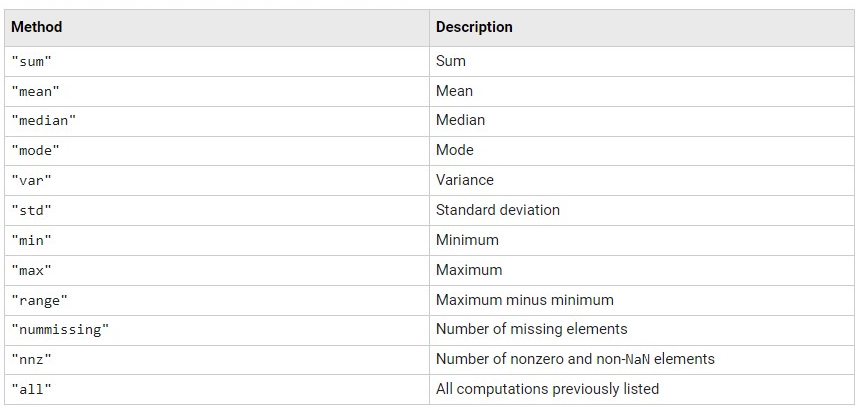

**Figura 4.-** Operaciones numéricas de una tabla

%Primero veremos el score promedio dependiendo del genero, utilizando la
%tabla 3
genderMean = groupsummary(dsStudents_3,"gender","mean") 

genderMean = 2×5 table
    gender    GroupCount    mean_mathScore    mean_readingScore    mean_writingScore
    ______    __________    ______________    _________________    _________________

    female       492            64.774             73.474               73.439      
    male         508             70.75             67.388               64.976      


%Podemos visualizar tambien el promedio dependiendo del grupo etnico
%utilizando la tabla 4
raceMean = groupsummary(dsStudents_4,"race_ethnicity","mean")

raceMean = 5×5 table
    race_ethnicity    GroupCount    mean_mathScore    mean_readingScore    mean_writingScore
    ______________    __________    ______________    _________________    _________________

       group A            79            65.696             69.203               67.848      
       group B           198            64.071              68.53               66.717      
       group C           323            65.511              68.61               66.805      
       group D           257            68.879              70.93               71.058      
       group E           143            77.427             76.615               75.035      


%Podemos realizar operaciones por conjuntos especificos por ejemplo de la
%siguiente manera
gen = dsStudents_2.gender;
race = dsStudents_2.race_ethnicity;
math = dsStudents_2.mathScore;
reading = dsStudents_2.readingScore;
writing = dsStudents_2.writingScore;
auxTable = table(gen,race,math, reading, writing)

auxTable = 1000×5 table
     gen       race      math    reading    writing
    ______    _______    ____    _______    _______

    female    group D     59       70         78   
    male      group D     96       93         87   
    female    group D     57       76         77   
    male      group B     70       70         63   
    female    group D     83       85         86   
    male      group C     68       57         54   
    female    group E     82       83         80   
    female    group B     46       61         58   
    male      group C     80       75         73   
    female    group C     57       69         77   
    male      group B     74       69         69   
    male      group B     53       50         49   
    male      group B     76       74         76   
    male      group A    

gender_raceMean = groupsummary(auxTable,["gen","race"],"mean")

gender_raceMean = 10×6 table
     gen       race      GroupCount    mean_math    mean_reading    mean_writing
    ______    _______    __________    _________    ____________    ____________

    female    group A        41         62.951         72.268          71.707   
    female    group B       112         62.268         72.384          71.893   
    female    group C       151          63.02         71.993          71.477   
    female    group D       118         63.839         72.873          74.161   
    female    group E        70         75.214         80.129          79.943   
    male      group A        38         68.658         65.895          63.684   
    male      group B        86         66.419         63.512          59.977   
    male      group C       172      

## *** Ejercicio ***

Realiza las siguientes operaciones 

- Cual es la media del grupo genero vs nivel de estudios de los padres

- Cual es el promedio de la raza etnica vs si se preparó o no para la prueba

- Cual es el promedio del genero vs si se preparó o no para la prueba

#### 1) Cual es la media del grupo genero vs nivel de estudios de los padres

% gen = dsStudents_2.gender;
levelOfEducation = dsStudents_2.parentalLevelOfEducation;
% math = dsStudents_2.mathScore;
% reading = dsStudents_2.readingScore;
% writing = dsStudents_2.writingScore;
auxTable1 = table(gen,levelOfEducation,math, reading, writing);
genderMeanvsLevelOfEducation = groupsummary(auxTable1,["gen","levelOfEducation"],"median")

genderMeanvsLevelOfEducation = 12×6 table
     gen       levelOfEducation     GroupCount    median_math    median_reading    median_writing
    ______    __________________    __________    ___________    ______________    ______________

    female    associate's degree       101             69               76                77     
    female    bachelor's degree         52             66               78                78     
    female    high school              116             61               71                69     
    female    master's degree           33             68               75                77     
    female    some college             106             66               74                75     
    female    some high school          84             62          

#### 2) Cual es el promedio de la raza etnica vs si se preparó o no para la prueba

preparationCourse= dsStudents_2.testPreparationCourse;

auxTable2 = table(race,preparationCourse,math, reading, writing);
genderMeanvsLevelOfEducation = groupsummary(auxTable2,["race","preparationCourse"],"mean")

genderMeanvsLevelOfEducation = 10×6 table
     race      preparationCourse    GroupCount    mean_math    mean_reading    mean_writing
    _______    _________________    __________    _________    ____________    ____________

    group A        completed            31         70.065         72.452          73.226   
    group A        none                 48         62.875         67.104          64.375   
    group B        completed            66         66.864         73.182          73.894   
    group B        none                132         62.674         66.205          63.129   
    group C        completed           101         66.782         72.614          73.426   
    group C        none                222         64.932         66.788          63.793   
    group D      

#### 3) Cual es el promedio del genero vs si se preparó o no para la prueba

auxTable3 = table(gen,preparationCourse,math, reading, writing);
genderMeanvsLevelOfEducation = groupsummary(auxTable3,["gen","preparationCourse"],"mean")

genderMeanvsLevelOfEducation = 4×6 table
     gen      preparationCourse    GroupCount    mean_math    mean_reading    mean_writing
    ______    _________________    __________    _________    ____________    ____________

    female        completed           177         67.565         77.729          79.864   
    female        none                315         63.206         71.083          69.829   
    male          completed           167         73.269         71.545          71.509   
    male          none                341         69.516         65.352          61.777   


### ### Modificación de las columnas en modelos de datos

Podemos realizar ligeras modificaciones a las columnas (caracteristicas de nuestro modelo de datos) realizando las siguientes operaciones

- Crear tablas a partir de datos específicos

- Agregar una columna de datos

- Mover columnas de datos

- Remover columnas de datos

%Creacion de tablas a partir de datos originales
auxTable_1 = table(gen, math, reading);
head(auxTable_1)


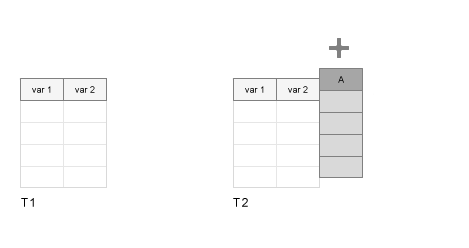

**Figura 5.- **Agregado de caracteristicas de un modelo de datos

%Agregado de valores a tablas ya existentes
auxTable_2 = addvars(auxTable_1,writing);
head(auxTable_2)


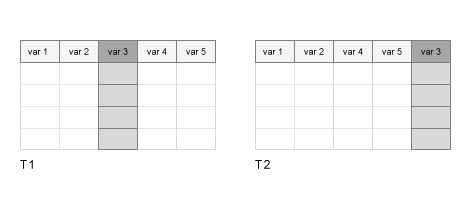

**Figura 6.- **Reordenamiento de caracteristicas de un modelo de datos

%Reordenamiento de caracteristicas de la tabla
auxTable_3 = movevars(auxTable_2,'reading','after','writing');
head(auxTable_3)


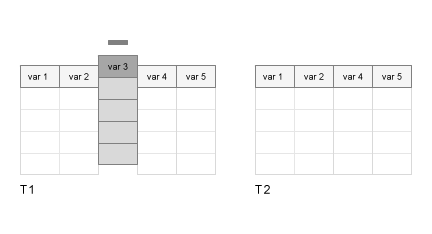

**Figura 7.- **Eliminacion de caracteristicas de un modelo de datos

%Eliminacion de caracteristicas de la tabla
auxTable_4 = removevars(auxTable_2,{'reading'});
head(auxTable_4)

### ###Filtrado de informacion basado en reglas de valores

%Podemos tambien filtrar los datos por grupos de informacion
%filtrado de la informacion de la tabla auxTable_2 para resultados de datos
%de prueba Matemáticas mayores a 60 pero menores a 80
auxTable = table(gen,math,reading,writing);
head(auxTable)

     gen      math    reading    writing
    ______    ____    _______    _______

    female     59       70         78   
    male       96       93         87   
    female     57       76         77   
    male       70       70         63   
    female     83       85         86   
    male       68       57         54   
    female     82       83         80   
    female     46       61         58   




mathBetween_60_80 = groupfilter(auxTable,"math",@(x) min(x) >= 60 && max(x) <= 80,"math");
head(mathBetween_60_80)

     gen      math    reading    writing
    ______    ____    _______    _______

    male       70       70         63   
    male       68       57         54   
    male       80       75         73   
    male       74       69         69   
    male       76       74         76   
    male       70       73         70   
    female     80       82         85   
    female     65       71         74   



auxMean_Table = groupsummary(mathBetween_60_80,"gen","max")

auxMean_Table = 2×5 table
     gen      GroupCount    max_math    max_reading    max_writing
    ______    __________    ________    ___________    ___________

    female       243           80           97             99     
    male         245           80           88             87     


## *** Ejercicio ***

Realiza las siguientes operaciones 

- Crea una tabla que contenga las siguientes categorias en este orden: Preparacion de la prueba, genero, Resultado de matemáticas, Resultado de lectura, Resultado de escritura

- Calcula el promedio de los tres valores de las pruebas y coloca el valor al final de las columnas

- Agrupa los resultados por promedio y clasificalos para valores mayores o iguales a 60 pero menores o iguales a 80. ¿Cuantos datos quedaron en total?

- Cual es el promedio general del género masculino que si se preparo para la prueba

- Cual es el promedio general del género femenino que no se preparo para la prueba

- De acuerdo con los datos, ¿Existe una relación directa entre prepararse para la prueba y no prepararse para la prueba?

#### **1) Crea una tabla que contenga las siguientes categorias en este orden: Preparacion de la prueba, genero, Resultado de matemáticas, Resultado de lectura, Resultado de escritura.**

Ej3auxTable1 = table(preparationCourse,gen,math,reading,writing);
head(Ej3auxTable1)

    preparationCourse     gen      math    reading    writing
    _________________    ______    ____    _______    _______

        completed        female     59       70         78   
        none             male       96       93         87   
        none             female     57       76         77   
        none             male       70       70         63   
        none             female     83       85         86   
        none             male       68       57         54   
        none             female     82       83         80   
        none             female     46       61         58   



#### **2) Calcula el promedio de los tres valores de las pruebas y coloca el valor al final de las columnas.**

Ej3auxTable2 = table(preparationCourse,gen,math,reading,writing);
head(Ej3auxTable2);

    preparationCourse     gen      math    reading    writing
    _________________    ______    ____    _______    _______

        completed        female     59       70         78   
        none             male       96       93         87   
        none             female     57       76         77   
        none             male       70       70         63   
        none             female     83       85         86   
        none             male       68       57         54   
        none             female     82       83         80   
        none             female     46       61         58   



promedio = mean([Ej3auxTable2.math, Ej3auxTable2.reading, Ej3auxTable2.writing], 2)

promedio =    69.0000
   92.0000
   70.0000
   67.6667
   84.6667
   59.6667
   81.6667
   55.0000
   76.0000
   67.6667


%Agregado de valores a tablas ya existentes
Ej3auxTable2_1  = addvars(Ej3auxTable2,promedio);
head(Ej3auxTable2_1)

    preparationCourse     gen      math    reading    writing    promedio
    _________________    ______    ____    _______    _______    ________

        completed        female     59       70         78            69 
        none             male       96       93         87            92 
        none             female     57       76         77            70 
        none             male       70       70         63        67.667 
        none             female     83       85         86        84.667 
        none             male       68       57         54        59.667 
        none             female     82       83         80        81.667 
        none             female     46       61         58            55 



#### 3) Agrupa los resultados por promedio y clasificalos para valores mayores o iguales a 60 pero menores o iguales a 80. ¿Cuantos datos quedaron en total?

%Reordenamiento de columna promedio de la tabla
Ej3auxTable3_1 = movevars(Ej3auxTable2_1,'promedio','Before','preparationCourse');
head(Ej3auxTable3_1)

    promedio    preparationCourse     gen      math    reading    writing
    ________    _________________    ______    ____    _______    _______

         69         completed        female     59       70         78   
         92         none             male       96       93         87   
         70         none             female     57       76         77   
     67.667         none             male       70       70         63   
     84.667         none             female     83       85         86   
     59.667         none             male       68       57         54   
     81.667         none             female     82       83         80   
         55         none             female     46       61         58   



%Agrupar por promedio
avgProm = groupsummary(Ej3auxTable3_1,["promedio","preparationCourse","gen"],"mean");
head(avgProm);

    promedio    preparationCourse     gen      GroupCount    mean_math    mean_reading    mean_writing
    ________    _________________    ______    __________    _________    ____________    ____________

         20           none           male          1            20             25              15     
     25.667           none           female        1            21             30              26     
     25.667           none           male          1            31             27              19     
         26           none           male          1            28             27              23     
     29.333           none           female        1            28             32              28     
     29.667           none           fem

%Valores mayores o iguales a 60 pero menores o iguales a 80
mathBetween_60_80 = groupfilter(avgProm,"promedio",@(x) min(x) >= 60 && max(x) <= 80,"promedio");
head(mathBetween_60_80);

    promedio    preparationCourse     gen      GroupCount    mean_math    mean_reading    mean_writing
    ________    _________________    ______    __________    _________    ____________    ____________

         60         none             male          3              65             59              56   
     60.333         completed        female        1              44             69              68   
     60.333         completed        male          1              64             62              55   
     60.333         none             female        1              52             66              63   
     60.333         none             male          3          68.333             56          56.667   
     60.667         completed        fem

suma = sum([mathBetween_60_80.GroupCount], 1);
disp(['En total quedaron: ', num2str(suma),' datos']);

En total quedaron: 511 datos


#### 4) Cual es el promedio general del género masculino que si se preparo para la prueba.

%Reordenamiento de columna promedio de la tabla para el ej 4
Ej3auxTable3_4 = movevars(Ej3auxTable2_1,'promedio','after','gen');
head(Ej3auxTable3_4);

    preparationCourse     gen      promedio    math    reading    writing
    _________________    ______    ________    ____    _______    _______

        completed        female         69      59       70         78   
        none             male           92      96       93         87   
        none             female         70      57       76         77   
        none             male       67.667      70       70         63   
        none             female     84.667      83       85         86   
        none             male       59.667      68       57         54   
        none             female     81.667      82       83         80   
        none             female         55      46       61         58   



%Agrupar por Curso de Preparación (principalmente)
avgProm4 = groupsummary(Ej3auxTable3_4,["preparationCourse","gen","promedio"],"mean");
%Filtro //Basado en una respuesta generada por ChatGPT.
filtro = (avgProm4.gen == 'male') & (avgProm4.preparationCourse == 'completed');
tabla_filtrada = avgProm4(filtro, :);
%Promedio de los estudiantes masculinos que se prepararon para la prueba
promedio_general_masculino_preparados = mean(tabla_filtrada.promedio);

disp(['Promedio general de estudiantes masculinos que se prepararon: ', num2str(promedio_general_masculino_preparados)]);

Promedio general de estudiantes masculinos que se prepararon: 72.2145


#### 5) Cual es el promedio general del género femenino que no se preparo para la prueba.

%Reordenamiento de columna promedio de la tabla para el ej 5
Ej3auxTable3_5 = movevars(Ej3auxTable2_1,'promedio','after','gen');
head(Ej3auxTable3_5);

    preparationCourse     gen      promedio    math    reading    writing
    _________________    ______    ________    ____    _______    _______

        completed        female         69      59       70         78   
        none             male           92      96       93         87   
        none             female         70      57       76         77   
        none             male       67.667      70       70         63   
        none             female     84.667      83       85         86   
        none             male       59.667      68       57         54   
        none             female     81.667      82       83         80   
        none             female         55      46       61         58   



%Agrupar por Curso de Preparación (principalmente)
avgProm4 = groupsummary(Ej3auxTable3_5,["preparationCourse","gen","promedio"],"mean");
%Filtro //Basado en una respuesta generada por ChatGPT.
filtro = (avgProm4.gen == 'female') & (avgProm4.preparationCourse == 'none');
tabla_filtrada = avgProm4(filtro, :);
%Promedio de los estudiantes femeninos que no se prepararon
promedio_general_masculino_preparados = mean(tabla_filtrada.promedio);

disp(['Promedio general de estudiantes femeninos que no se prepararon: ', num2str(promedio_general_masculino_preparados)]);

Promedio general de estudiantes femeninos que no se prepararon: 65.8833


#### 6) De acuerdo con los datos, ¿Existe una relación directa entre prepararse para la prueba y no prepararse para la prueba?

Si existe una relación directamente proporcional. Los primeros 5 estudiantes con la mayor calificación tomaron el curso de preparación para la prueba y en los promedio más bajos estan aquellos que no tomaron el curso de preparación. En los resultados entre 60 y 80 de promedio, hay una diferencia aproximada de 6 puntos entre aquellos que no tomaron el curso contra aquellos que si lo tomaron y salieron un poco más por encima.

### ### Discretizacion de datos en categorias

%Vamos a establecer los siguientes valores de calificaciones en el formato
%americano de calificaciones donde
%Valor | calificacion
%0 59  | F
%60 69 | D
%70 79 | C
%80 89 | B
%90 99 | A
%100   | A+

%Primero estableceremos nuestras nuevas categorias de datos
%etiquetas
calAme = {'F', 'D', 'C', 'B', 'A', 'A+'};

%Limites de calificaciones
limit = [0 59 69 79 89 99 100];
auxVal = dsStudents_3.mathScore; %Solo para guardar el valor
dsStudents_3.mathScore = discretize(dsStudents_3.mathScore, limit, 'categorical', calAme);
summary(dsStudents_3.mathScore)
head(dsStudents_3)
dsStudents_3.mathScore = auxVal; %Regreso el valor original para no entorpecer la BD
head(dsStudents_3)

### ### Gráficos 

Existen distintas formas de visualizar la información. 

#### ---Histogramas

Por ejemplo podemos ver la distribucion de datos mediante un histograma

%Muestra el histograma de los datos que pertenecen a un genero masculino o
%femenino 
close all
fig01=figure;
hold on
    histogram(genero,'BarWidth',0.5)
    ylabel("Número de muestras")
    xlabel("Categorias de género")
hold off

#### ---Swarm

fig02=figure;
hold on
%Esta gráfica nos muestra las categorias y la densidad de valores numéricos
%asociados a cada categoria
    %En el eje X colocaremos las categorias que queremos visualizar
    x=categorical(dsStudents_2.gender);

    %Por su parte, en el eje y colocaremos los valores numéricos que
    %queremos visualizar, en este caso los valores de la prueba de
    %matemáticas
    y=dsStudents_2.mathScore;

    swarmchart(x,y);
hold off


#### ---Swarm 3D

fig03=figure;
hold on 
    %Podemos realizar una densidad de datos en tres dimensiones de la
    %siguiente manera
    %En el eje x tendremos nuestra primer categoria de datos
    x=categorical(dsStudents_2.gender);

    %En el eje y tendremos nuestra segunda categoria de datos
    y=categorical(dsStudents_2.race_ethnicity);

    %Finalmente en el eje z tendremos la densidad de datos de la prueba de
    %matemáticas

    z=dsStudents_2.mathScore;
    swarmchart3(x,y,z,50,genero,'*')
    
    view([60 40])
    grid minor
    set(gca,'FontSize'       ,20,...
         'MinorGridColor' ,'g',...
        'GridColor'      ,'r',...
        'Xgrid'          ,'on',...
        'Ygrid'          ,'on',...
        'LineWidth'      ,2)
hold off

#### ---Gráficos de pay

%Primero creamos nuestras categorias
%El nivel de educacion de los padres y el genero del hijo
nivelEducacion=dsStudents_2.parentalLevelOfEducation;
    nivelEducacionyGeneroF = nivelEducacion(dsStudents_2.gender == 'female');
    nivelEducacionyGeneroM = nivelEducacion(dsStudents_2.gender == 'male');
grpCatEtn = categories(dsStudents_2.parentalLevelOfEducation);

fig04=figure;
hold on
    t=tiledlayout(1,2,'TileSpacing','compact');
    ax1 = nexttile;
        pie(nivelEducacionyGeneroF)
        title('Género femenino')
    ax2 = nexttile;
        pie(nivelEducacionyGeneroM)
        title('Género masculino')
    lgd = legend(grpCatEtn);
    lgd.Layout.Tile = 'east';
hold off

#### ---Scatter(gráfico "x" VS "y")

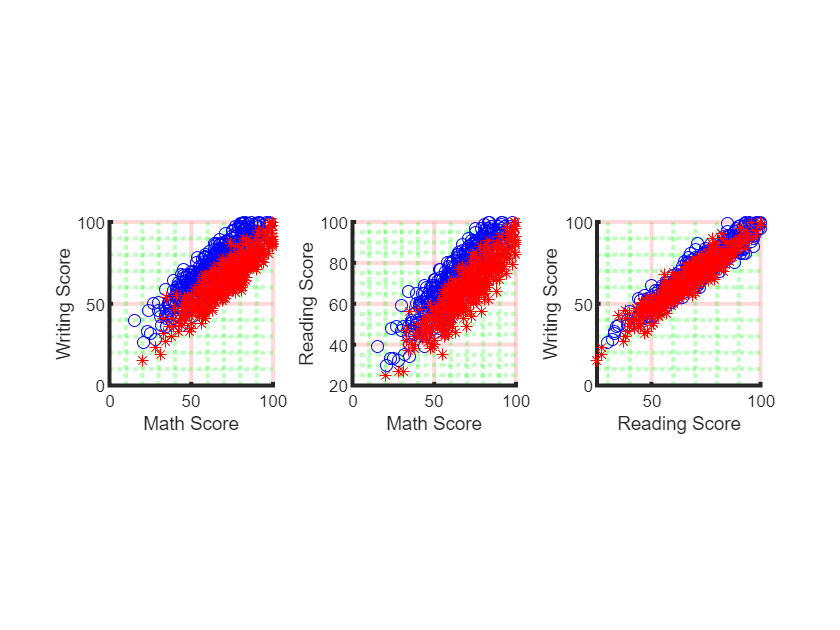

valMathScore_F = dsStudents_3.mathScore(genero == 'female');
valMathScore_M = dsStudents_3.mathScore(genero == 'male');

valReadingScore_F = dsStudents_3.readingScore(genero == 'female');
valReadingScore_M = dsStudents_3.readingScore(genero == 'male');

valWritingScore_F = dsStudents_3.writingScore(genero == 'female');
valWritingScore_M = dsStudents_3.writingScore(genero == 'male');

fig05=figure;
t=tiledlayout(1,3,'TileSpacing','compact');
ax1 = nexttile;
    hold on
        axis square;
        scatter(valMathScore_F,valWritingScore_F,'bo');
        scatter(valMathScore_M,valWritingScore_M,'r*');
        xlabel('Math Score')
        ylabel('Writing Score')
        grid minor
        set(gca,'MinorGridColor' ,'g',...
                'GridColor'      ,'r',...
                'Xgrid'          ,'on',...
                'Ygrid'          ,'on',...
                'LineWidth'      ,2)
    hold off
ax2 = nexttile;
    hold on
        axis square;
        scatter(valMathScore_F,valReadingScore_F,'bo');
        scatter(valMathScore_M,valReadingScore_M,'r*');
        xlabel('Math Score')
        ylabel('Reading Score')
        grid minor
        set(gca,'MinorGridColor' ,'g',...
                'GridColor'      ,'r',...
                'Xgrid'          ,'on',...
                'Ygrid'          ,'on',...
                'LineWidth'      ,2)
    hold off    
ax3 = nexttile;
    hold on
        axis square;
        scatter(valReadingScore_F,valWritingScore_F,'bo');
        scatter(valReadingScore_M,valWritingScore_M,'r*');
        xlabel('Reading Score')
        ylabel('Writing Score')
        grid minor
        set(gca,'MinorGridColor' ,'g',...
                'GridColor'      ,'r',...
                'Xgrid'          ,'on',...
                'Ygrid'          ,'on',...
                'LineWidth'      ,2)
    hold off   

#### ---Scatter 3D ("x" Vs "y" Vs "z")

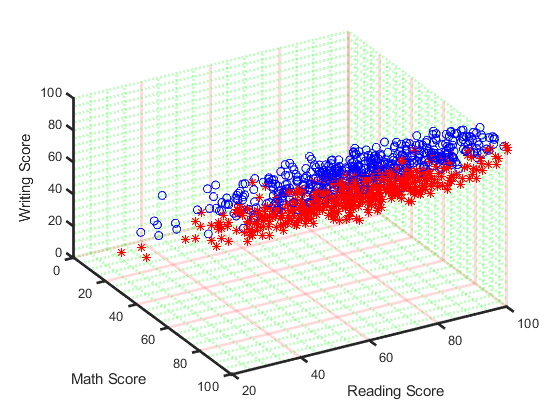

fig06=figure;
hold on
    scatter3(valMathScore_F,valReadingScore_F,valWritingScore_F,'bo');
    scatter3(valMathScore_M,valReadingScore_M,valWritingScore_M,'r*');
    xlabel('Math Score')
    ylabel('Reading Score')
    zlabel('Writing Score')
    view([60 40])
    grid minor
    set(gca,'MinorGridColor' ,'g',...
            'GridColor'      ,'r',...
            'Xgrid'          ,'on',...
            'Ygrid'          ,'on',...
            'LineWidth'      ,2)
hold off     

#### --- Group Scatter (gráfica que automatiza la distribucion "x" VS "y" dados ciertos grupos

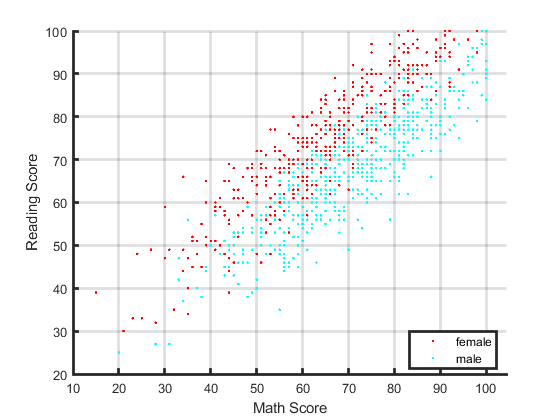

fig07 = figure;
hold on
    gscatter(dsStudents_3.mathScore,dsStudents_3.readingScore,dsStudents_3.gender)
    xlabel('Math Score')
    ylabel('Reading Score')
    grid on
    %grid minor
    set(gca,'Xgrid'          ,'on',...
            'Ygrid'          ,'on',...
            'LineWidth'      ,2)
hold off

#### --- Matrix Scatter 

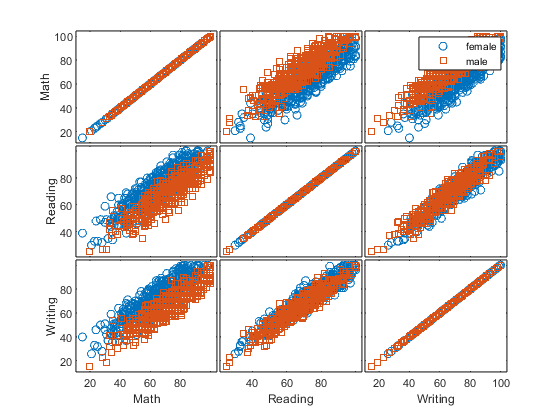

xvars = [dsStudents_3.mathScore, dsStudents_3.readingScore, dsStudents_3.writingScore];
yvars = [dsStudents_3.mathScore, dsStudents_3.readingScore, dsStudents_3.writingScore];
colors = [0      0.4470 0.7410;...
          0.8500 0.3250 0.0980;...
          0.4940 0.1840 0.5560];
grp = dsStudents_3.gender;
labels = {'Math', 'Reading', 'Writing'};
fig08 = figure;
hold on
    [h,ax] = gplotmatrix(xvars,yvars,grp,colors,'os*x.');
    for i = 1:3
        xlabel(ax(3,i), labels{i})
        ylabel(ax(i,1), labels{i})
    end
hold off

#### ---Gráfico de cajas

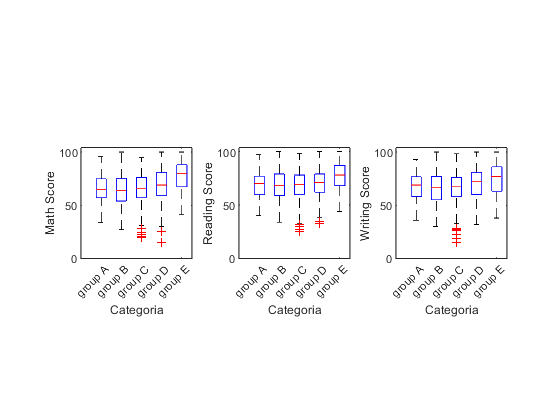

fig09 = figure;
subplot(1,3,1)
    hold on
        axis square;
        boxplot(dsStudents_2.mathScore,dsStudents_2.race_ethnicity)
        xlabel('Categoria')
        ylabel('Math Score')

    hold off
subplot(1,3,2)
    hold on
        axis square;
        boxplot(dsStudents_2.readingScore,dsStudents_2.race_ethnicity)
        xlabel('Categoria')
        ylabel('Reading Score')

    hold off
subplot(1,3,3)
    hold on
        axis square;
        boxplot(dsStudents_2.writingScore,dsStudents_2.race_ethnicity)
        xlabel('Categoria')
        ylabel('Writing Score')
    hold off    

#### ---Gráfico de coordenadas paralelas

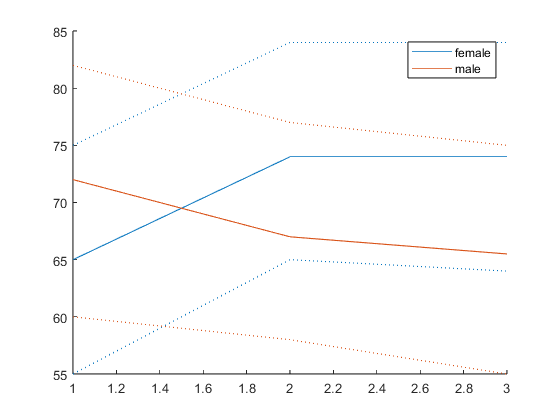

%Datos categoricos
gen = dsStudents_2.gender;
race = dsStudents_2.race_ethnicity;

%Datos numéricos
math = dsStudents_2.mathScore;
reading = dsStudents_2.readingScore;
writing = dsStudents_2.writingScore;

%Tabla auxiliar
auxTable = table(gen,math,reading,writing);
%auxGrpTable = 
fig10 = figure;
hold on
    parallelcoords(xvars,"Group",grp,"Quantile",0.25)
hold off

## *** Ejercicio ***

Realiza las siguientes operaciones

- Clasifica los datos por raza y por genero

- Muestra una figura de histograma basado en esta clasificación: tres gráficas (pruebas de matemáticas, lectura y escritura) con dos categorias del histograma [femenino y masculino]

- Muestra una figura de histograma basado en esta clasificiación: cinco gráficas con tres categorias (pruebas de matemáticas, de lectura y de escritura)

- Muestra una figura de "Swarm 3D" basado en esta clasificación: tres gráficas con cinco categorias en x (los cinco grupos de razas) seis categorias en y (correspondientes a los grados de educacion de los padres) y dependiendo de la prueba realizada los datos de matemáticas, lectura y escritura

- Muestra en una figura de pay cual es el porcentaje de genero que tuvo un curso de preparacion y cuantos de estos obtuvieron una nota promedio aprobatoria

- Muestra en una figura de gráficos de caja, cual es la distribucion de aquellos que desayunaron vs aquellos que obtuvieron una nota promedio aprobatoria